**Initialize:**

n = 1201;                   % Number of locations to evaluate bridge failure
L = 1200;                   % Length of bridge
x = linspace(0, L, n);      % Define x coordinate
P_each = [-66.7 -66.7 -66.7 -66.7 -90 -90]; % Set train load as 6 point loads applied via the wheels
self = 0.00613; % Self Weight

**Load Case 2:**

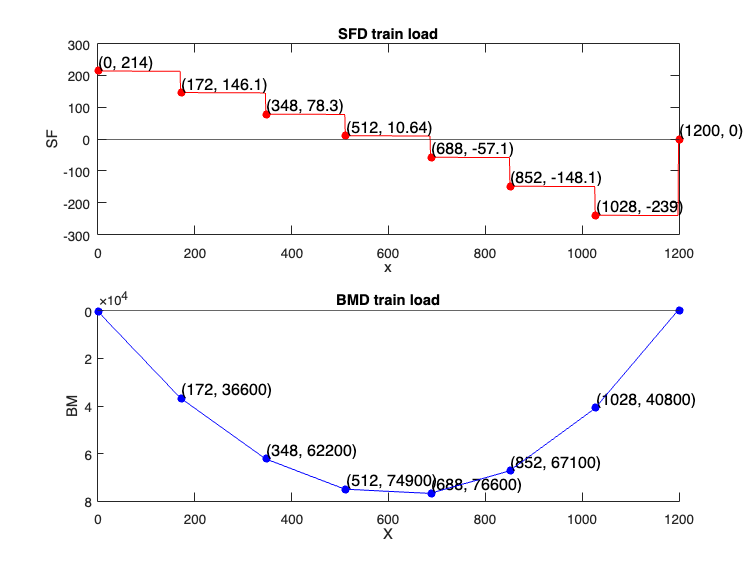

x0 = 172; % First Point Position
SFD_TL = zeros(1,n);
total_loads = zeros(1, n);
    x_load = [x0,x0+176,x0+340,x0+516,x0+680,x0+856];
    totalB = 0;
    total_load = 0;

    % Support Reactions
    for i = 1:6
        totalB = totalB + (x_load(1,i)*P_each(1,i));
        total_load = total_load + P_each(1,i);
    end
    total_load = total_load - self*L;
    Sup_B = -(totalB - (self*L*L)/2)/L;
    Sup_A = -total_load - Sup_B;
    SFD_TL(1,1) = Sup_A;
    SFD_TL(1,L) = Sup_B;

% Creating Points for SFD
for i = 1:6
    SFD_TL(1,x_load(1,i)) = SFD_TL(1,x_load(1,i)) + P_each(1,i);
end

for c = 2:L-1
    SFD_TL(1,c) = SFD_TL(1,c) + SFD_TL(1,c-1)-self;
end

SFD_TL(1,L) = SFD_TL(1,L-1) + Sup_B;

%SFD 
subplot(2,1,1)
plot(x, SFD_TL,'red') % plot the SF_matrix against x
hold on
% Add Data Points
shearLabel = zeros(1,6);
for i = 1:6
scatter(x_load(i), SFD_TL(x_load(i)), "filled", "red")
SFD_str = num2str(abs(SFD_TL(x_load(i))));
if str2num(SFD_str(1)) == 1
shearLabel(i)=round(SFD_TL(x_load(i)),4,"significant");
else
shearLabel(i)=round(SFD_TL(x_load(i)),3,"significant");
end
end

for i = 1:6
text(x_load(i), SFD_TL(x_load(i)), "("+num2str(x_load(i)) +", " +shearLabel(i) +")", 'VerticalAlignment','bottom','FontSize',12);
end

scatter(1200,SFD_TL(1200),  "filled", "red")
text(1200, SFD_TL(1200), "("+num2str(1200) +", " + 0 +")", 'VerticalAlignment','bottom','FontSize',12);

SFD_str = num2str(abs(SFD_TL(1)));
if str2num(SFD_str(1)) == 1
shearLabel(1)=round(SFD_TL(1),4,"significant");
else
shearLabel(1)=round(SFD_TL(1),3,"significant");
end
scatter(1,SFD_TL(1), "filled", "red")
text(0, SFD_TL(1), "("+num2str(0) +", " + shearLabel(1) +")", 'VerticalAlignment','bottom','FontSize',12);
yline(0)

%Labels
xlabel('x')
ylabel('SF')
title('SFD train load')
hold off

%BMD
BMD_TL = cumsum(SFD_TL);
BMD_TL(n) = 0;

subplot(2,1,2)
hold on

%Add Data Labels
BMDLabel = zeros(1,6);
for i = 1:6
scatter(x_load(i), BMD_TL(x_load(i)), "filled", "blue")
BMD_str = num2str(abs(BMD_TL(x_load(i))));
if str2num(BMD_str(1)) == 1
BMDLabel(i)=round(BMD_TL(x_load(i)),4,"significant");
else
BMDLabel(i)=round(BMD_TL(x_load(i)),3,"significant");
end
end
for i = 1:6
text(x_load(i), BMD_TL(x_load(i)), "("+num2str(x_load(i)) +", " +BMDLabel(i) +")", 'VerticalAlignment','bottom','FontSize',12);
end
scatter(1, BMD_TL(1), "filled", "blue")
scatter(1200, BMD_TL(1200), "filled", "blue")
yline(0)
plot(x, BMD_TL,'blue') % plot the BM_matrix against x
xlabel('X')
ylabel('BM')
title('BMD train load')
set(gca, 'YDir', 'reverse')
hold off

**Cross-Sections:**

%% 2. Define Cross-Section Inputs & Calculate Cross-Section Properties
% Design0 Cross Section Inputs
xc = [0 400 800 L]; % Location, x, of cross-section change
tfb = [100 100 100 100]; % Top Flange Width
tft = [1.27 1.27 1.27 1.27]; % Top Flange Thickness
wh = [73.73 73.73 73.73 73.73]; % Web Height
wt = [1.27 1.27 1.27 1.27]; % Web Thickness (Assuming 2 separate webs)
ws = [80 80 80 80]; % Web Spacing
bfb = [80 80 80 80]; % Bottom Flange Width
bft = [1.27 1.27 1.27 1.27]; % Bottom Flange Thickness
gtb = [5 5 5 5]; % Glue Tab Width
gtt = [1.27 1.27 1.27 1.27]; % Glue Tab Thickness

% Interpolate values across every mm of bridge
tfb = interp1(xc, tfb, x);
tft = interp1(xc, tft, x);
wh = interp1(xc, wh, x);
wt = interp1(xc, wt, x);
ws = interp1(xc, ws, x);
bfb = interp1(xc, bfb, x);
bft = interp1(xc, bft, x);
gtb = interp1(xc, gtb, x);
gtt = interp1(xc, gtt, x);

% Calculate cross-section properties
[ybot, ytop, I, Qcent, Qglue] = SectionProperties(x, n, tfb, tft, wh, wt, bfb, bft, gtb, gtt)

ybot =    41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311   41.4311


ytop =    34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389   34.8389


I = 1.0e+05 *

    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835    4.1835


Qcent = 1.0e+03 *

    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933    6.1933


Qglue = 1.0e+03 *

    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439    4.3439


**Material Properties**

%% 3. Define Material Properties
SigT = 30;  % Tensile strength
SigC = 6;   % Compressive strength
E = 4000;   % Young's Modulus
TauU = 4;   % Shear strength, matboard
TauG = 2;   % Shear strength, glue
mu = 0.2;   % Poisson's ratio

**Compression and Tension Stress:**

m = max(BMD_TL)     

m = 7.6653e+04

    s_top = (m*ytop)/I

s_top = 6.3834

    s_bot = (m*ybot)/I

s_bot = 7.5913

    FOS_C = SigC/s_top

FOS_C = 0.9399

    FOS_T = SigT/s_bot

FOS_T = 3.9519

**SFD and BMD Envelope:**

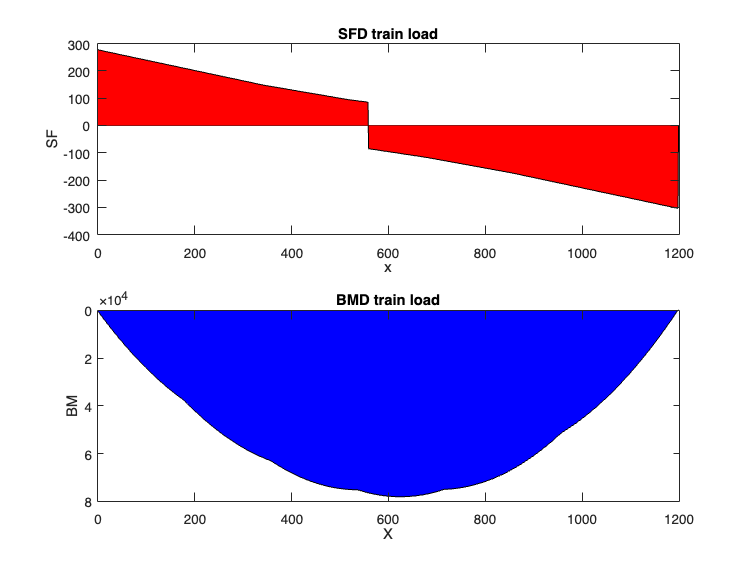

P_each = [-66.7 -66.7 -66.7 -66.7 -90 -90]; % Set train load as 6 point loads applied via the wheels
self = 0.00613; % Self Weight
n = 1201;
L = 1200;
x = linspace(0, L, n);

for k = -854:1199
    SFD_TL = zeros(1,n);
    BMD_TL = zeros(1,n);
    total_loads = zeros(1, n);
    x0 = k;
    x_load = [x0,x0+176,x0+340,x0+516,x0+680,x0+856];
    totalB = 0;
    total_load = 0;
    % Support Reactions
    for i = 1:6
        if x_load(1,i)>1 && x_load(1,i)<=1197
        totalB = totalB + (x_load(1,i)*P_each(1,i));
        total_load = total_load + P_each(1,i);
        end
    end

    total_load = total_load - self*L;
    Sup_B = -(totalB - (self*L*L)/2)/L;
    Sup_A = -total_load - Sup_B;
    SFD_TL(1,1) = Sup_A;
    SFD_TL(1,L) = Sup_B;

for i = 1:6
    if 1<x_load(1,i) && x_load(1,i)<=1197
        SFD_TL(1,x_load(1,i)) = SFD_TL(1,x_load(1,i)) + P_each(1,i);
    end
end

for p = 2:L-1
    SFD_TL(1,p) = SFD_TL(1,p) + SFD_TL(1,p-1)-self;
end
    SFD_TL(1,L) = SFD_TL(1,L-1) + Sup_B;
    BMD_TL = cumsum(SFD_TL);
    BMD_TL(n) = 0;

    SFD_TL_Total(k+855,:) = SFD_TL;
    BMD_TL_Total(k+855,:) = BMD_TL;
end
SFD_Env = zeros(1,L);
 for i = 1:n
    if max(SFD_TL_Total(:,i)) > -(min(SFD_TL_Total(:,i)))
     SFD_Env(1,i) = max(SFD_TL_Total(:,i));
    else
     SFD_Env(1,i) = min(SFD_TL_Total(:,i));
    end
    BMD_Env(1,i) = max(BMD_TL_Total(:, i));
 end
subplot(2,1,1)
plot(x, SFD_Env, "red")
area(x, SFD_Env, 'FaceColor',"r")
xlabel('x')
ylabel('SF')
title('SFD train load')

subplot(2,1,2)
plot(x, BMD_Env,'blue') % plot the BM_matrix against x
area(x, BMD_Env, 'FaceColor',"b")
xlabel('X')
ylabel('BM')
title('BMD train load')
set(gca, 'YDir', 'reverse')

**Functions:**

function [ybot, ytop, I, Qcent, Qglue] = SectionProperties ( x, n, ...
    tfb, tft, wh, wt, bfb, bft, gtb, gtt )
% Calculates important sectional properties for left half .
% Including but not limited to ybar, I, Q, etc.
% Input: Geometric Inputs. Format will depend on user
% Output: Sectional Properties at every value of x.
% Each property is a 1-D array of length n

ovheight = tft + wh + bft; % Total height along beam

% Initialize A
tfa = zeros(1, n);
bfa = zeros(1, n);
wa = zeros(1, n);
gta = zeros(1, n);

% Initialize I_0
tfI = zeros(1, n);
bfI = zeros(1, n);
wI = zeros(1, n);
gtI = zeros(1, n);

tfIsum = zeros(1, n);
bfIsum = zeros(1, n);
wIsum = zeros(1, n);
gtIsum = zeros(1, n);

% Initialize ybar, I
ybot = zeros(1, n);
ytop = zeros(1, n);
I = zeros(1, n);

% Initialize Q sum value(s), Qcent, Qglue
wQ = zeros(1, n);
Qcent = zeros(1, n);
Qglue = zeros(1, n);

for i = 1:length(x)
    % Areas, A
    tfa(i) = tfb(i) * tft(i);
    % Assumes all values have been interpolated already
    bfa(i) = bfb(i) * bft(i); 
    % If thickness remains constant, use # instead of vector
    wa(i) = 2 * wh(i) * wt(i); % Assumes 2 webs
    gta(i) = 2 * gtb(i) * gtt(i); % Assumes 2 glue tabs
    
    % Local centroids, y
    tfy = ovheight - (tft ./ 2);
    bfy = bft ./ 2;
    wy = (wh ./ 2) + bft;
    gty = ovheight(i) - tft(i) - (gtt ./ 2);

    % Global centroid, ybar
    ybot(i) = (tfa(i) * tfy(i) + bfa(i) * bfy(i) + wa(i) * wy(i) + ...
        gta(i) * gty(i)) / (tfa(i) + bfa(i) + wa(i) + gta(i));
    ytop(i) = abs(ybot(i) - ovheight(i));
    
    % I naught, I_0
    tfI(i) = (tfb(i) * (tft(i)^3)) / 12;
    bfI(i) = (bfb(i) * (bft(i)^3)) / 12;
    wI(i) = 2 * (wt(i) * (wh(i)^3)) / 12;
    gtI(i) = 2 * (gtb(i) * (gtt(i)^3)) / 12;

    tfIsum(i) = tfI(i) + tfa(i) * (abs(ybot(i) - tfy(i)))^2;
    bfIsum(i) = bfI(i) + bfa(i) * (abs(ybot(i) - bfy(i)))^2;
    wIsum(i) = wI(i) + wa(i) * (abs(ybot(i) - wy(i)))^2;
    gtIsum(i) = gtI(i) + gta(i) * (abs(ybot(i) - gty(i)))^2;

    % Second moment of area, I
    I(i) = tfIsum(i) + bfIsum(i) + wIsum(i) + gtIsum(i);

    % First moment of area, Q (Qcent & Qglue)
    wQ(i) = (2 * wt(i) * (ybot(i)-bft(i))) * ((ybot(i)-bft(i))/2);
    Qcent(i) = bfa(i) * (ybot(i)-(bft(i)/2)) + wQ(i);
    Qglue(i) = tfa(i) * (tfy(i) - ybot(i));
end
end